## **Model Risk-Immune Robust Anomaly Detectors**

**Authors: Venkatraman Renganathan, Benjamin Gravell, Justin Ruths, and Tyler Summers -- UT Dallas**

**IEEE Conference on Decision & Control, Austin, TX, USA Dec, 2021.      **

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Created on 7 November 2021
% @author: Venkatraman Renganathan - Lund University & UT DALLAS
%
% This script simulates Stochastic Discrete Time LTV Systems with 
% distributionally robust thresholds obtained via s-moments ambiguity set.
% This script is tested in Matlab 2020b, MacOS, 64-bit
% (C) Venkatraman Renganathan, 2021. Email: venkat@control.lth.se
%
% This program is a free software: you can redistribute it and/or modify it
% under the terms of the GNU lesser General Public License, either version 
% 2018b, or any later version. This program is distributed in the hope that 
% it will be useful, but WITHOUT ANY WARRANTY. 
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Jacobian based Linearization of simple inverted pendulum

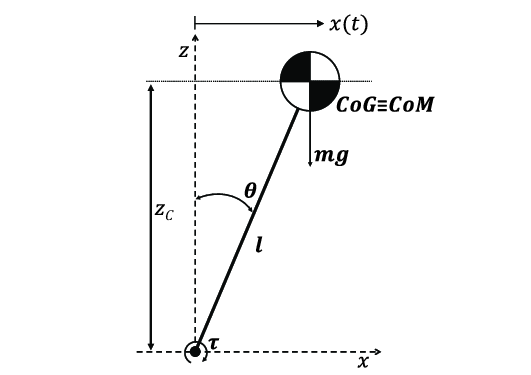

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Start fresh - Clear and close previous simulation results
%
clear; close all; clc;
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Problem setting
fprintf('Setting the problem data for pendulum system');

Setting the problem data for pendulum system

n = 2; % Number of states
m = 1; % Number of controls
p = 1; % Number of outputs
T = 10000000; % Simulation time horizon
dt = 0.1; % Step size for Euler discretization

% Define the pendulum system and get system object
sys = Define_Pendulum_System(n,m,p,dt);

Defining the Jacobian
 No uncertainty in B matrix

### Simulate the System & Collect the Residuals

% Simulate the system
fprintf('Simulating the system using standard LQG \n');

Simulating the system using standard LQG 



% Compute simple LQG 
fprintf('\n Computing the Kalman Gain using standard LQG');


 Computing the Kalman Gain using standard LQG

fprintf('\n LQG K matrix:');


 LQG K matrix:

sys.K = -dlqr(sys.A, sys.B, sys.Q, sys.R);
display(sys.K)

   -9.1395   -4.1530



fprintf('\n LQG L matrix:');


 LQG L matrix:

sys.L = dlqr(sys.A', sys.C', sys.sigmaW, sys.sigmaV)';
display(sys.L)

    0.7428
    1.1512



[sys.X, ~, ~] = idare(sys.A, sys.B, sys.Q, sys.R);
% [~, sys.L, ~] = kalman(sys.sssys, sys.sigmaW, sys.sigmaV);

% Define the initial conditions
x_0 = [pi; 0]; % Mean of state
V_0 = eye(n); % Covariance of state 

% Use this to compute the residual 
% P = dare((A-L*C)',zeros(n,n),L*Sigma_v*L'+Sigma_w,eye(n))
steady_moments = Compute_Steady_State_Moments(sys);
sys.sigmaR = steady_moments.R_infty; 
sys.Xinfty = steady_moments.X_infty;
sys.XinftyFrob = norm(sys.Xinfty, "fro");
fprintf('SigmaR from LQG: \n');

SigmaR from LQG: 


display(sys.sigmaR);

   10.4942



fprintf('X_Infinity from LQG \n');

X_Infinity from LQG 


display(sys.Xinfty);

  373.8102  -28.9094
  -28.9094  378.1881



fprintf('Frobenius Norm of X_Infinity from LQG \n');

Frobenius Norm of X_Infinity from LQG 


display(sys.XinftyFrob);

  533.3215



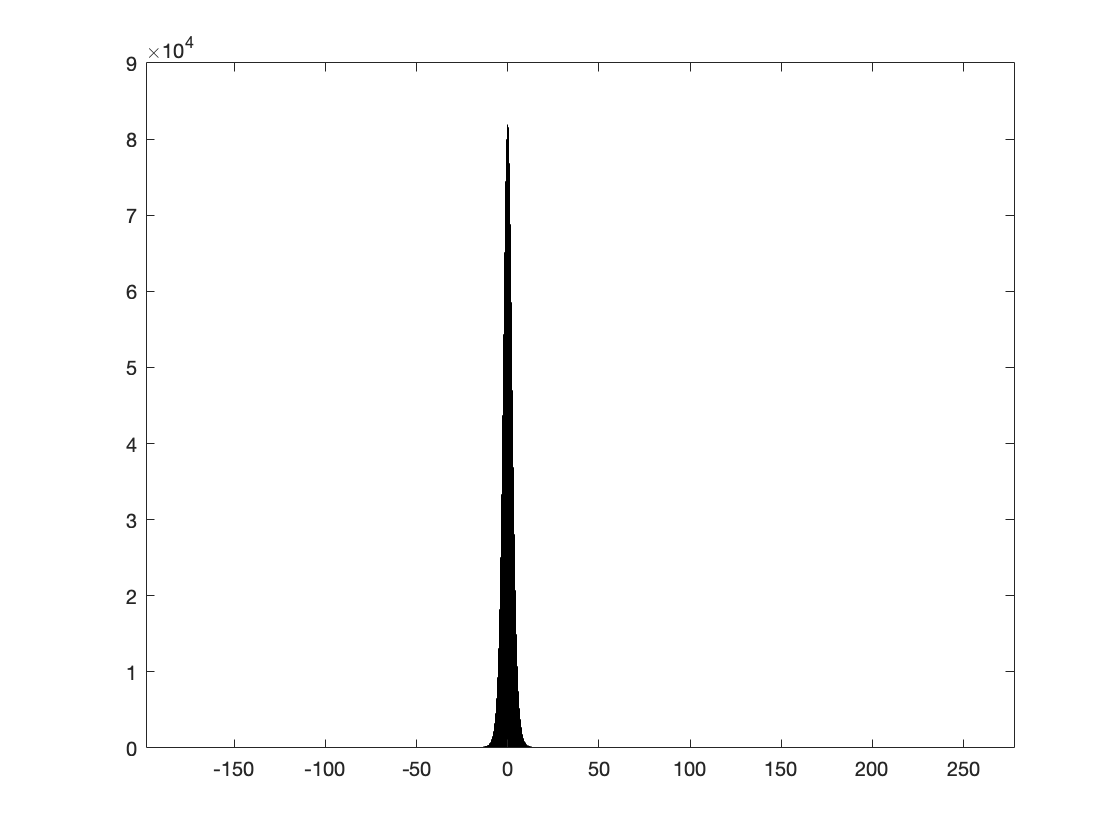


% Generate the required true data (state,output, distance measure)
q_lqg = Generate_Distance_Measure_Data(sys, x_0, T);        

q_lqg = q_lqg(:);
q_lqg_mean = mean(q_lqg);
fprintf('Mean of Distance Measure data from LQG is: %.3f \n', q_lqg_mean);    

Mean of Distance Measure data from LQG is: 0.838 


fprintf('Finished Collecting the LQG Residuals \n');    

Finished Collecting the LQG Residuals 


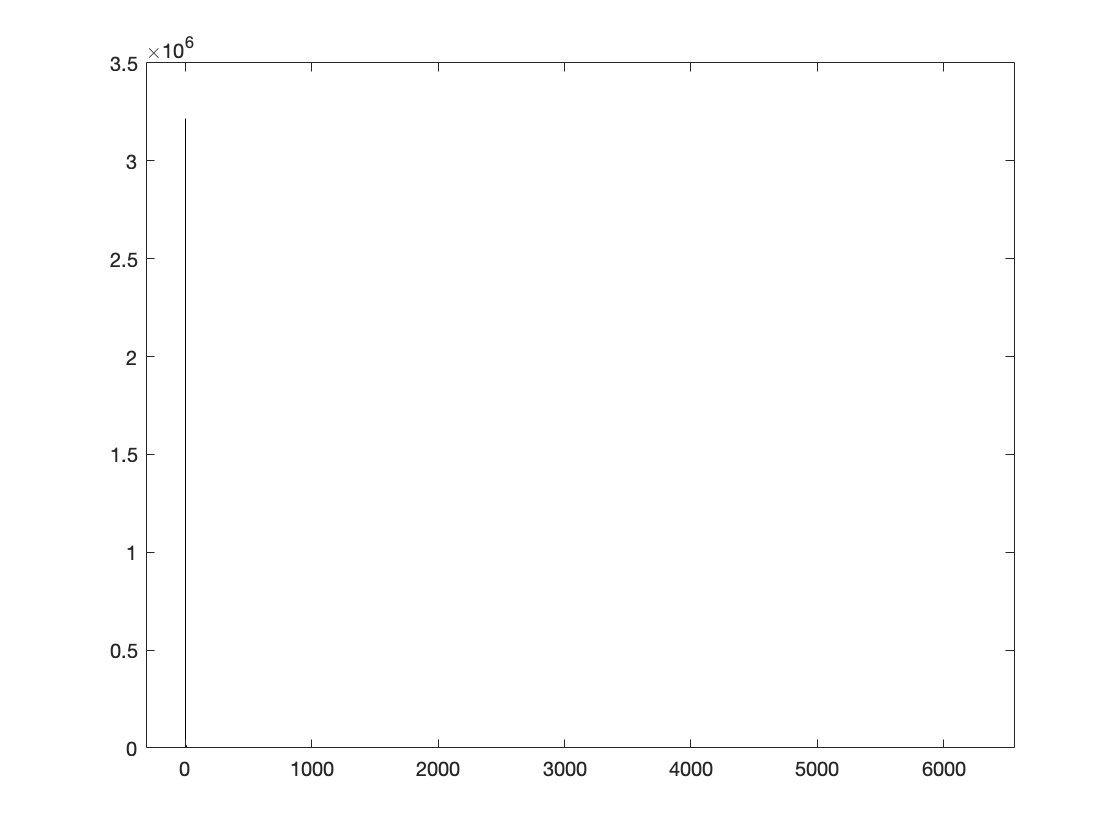


figure;
histogram(q_lqg);


% Simulate the system
fprintf('Simulating the system using MLQG \n');

Simulating the system using MLQG 



% Compute the K,L matrices using multiplicative noise driven LQG
fprintf('\n Computing the Kalman Gain using MLQG Coupled Riccatti Equations');    


 Computing the Kalman Gain using MLQG Coupled Riccatti Equations

[sys.K, sys.L, sys.sigmaE] = Solve_Coupled_Riccati(sys);

Value Iteration Converged 


P1 =   458.1997  147.8412
  147.8412   60.2735


P2 =   597.9700 -205.6496
 -205.6496  271.8496


P3 =     4.3052    7.5760
    7.5760   52.2783


P4 =    38.2713  -23.2766
  -23.2766   61.7345


fprintf('\n MLQG K matrix:');


 MLQG K matrix:

display(sys.K)

  -11.1046   -4.6831



fprintf('\n MLQG L matrix:');


 MLQG L matrix:

display(sys.L)

    0.7976
    1.5326



fprintf('\n MLQG SigmaE matrix:');


 MLQG SigmaE matrix:

display(sys.sigmaE)

    4.3052    7.5760
    7.5760   52.2783




% Check code
% P = dlyap(sys.A-sys.L*sys.C, sys.sigmaW + sys.L*sys.sigmaV*sys.L');
% display(P);

% Define the initial conditions
x_0 = [pi; 0]; % Mean of state
V_0 = eye(n); % Covariance of state 

% Use this to compute the residual 
steady_moments = Compute_Steady_State_Moments(sys);
sys.sigmaR = steady_moments.R_infty;  
sys.Xinfty = steady_moments.X_infty;
sys.XinftyFrob = norm(sys.Xinfty, "fro");
fprintf('SigmaR from MLQG: \n');

SigmaR from MLQG: 


display(sys.sigmaR);

    6.3052



fprintf('X_Infinity from MLQG \n');

X_Infinity from MLQG 


display(sys.Xinfty);

   42.5765  -15.7006
  -15.7006  114.0128



fprintf('Frobenius Norm of X_Infinity from MLQG \n');

Frobenius Norm of X_Infinity from MLQG 


display(sys.XinftyFrob);

  123.7122



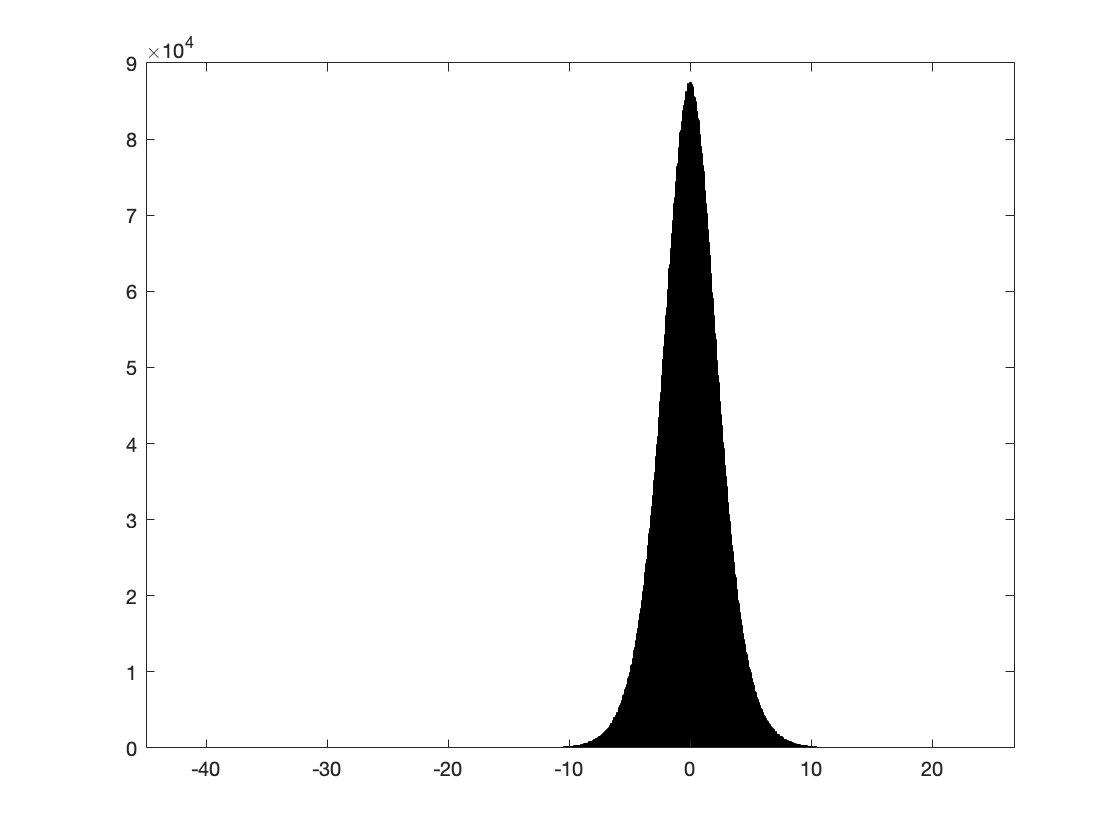


% Generate the required true data (state,output, distance measure)
q = Generate_Distance_Measure_Data(sys, x_0, T);        

q = q(:);
q_mlqg_mean = mean(q);
fprintf('Mean of Distance Measure data from MLQG is: %.3f \n', q_mlqg_mean);

Mean of Distance Measure data from MLQG is: 1.008 


fprintf('Finished Collecting the MLQG Residuals \n');

Finished Collecting the MLQG Residuals 


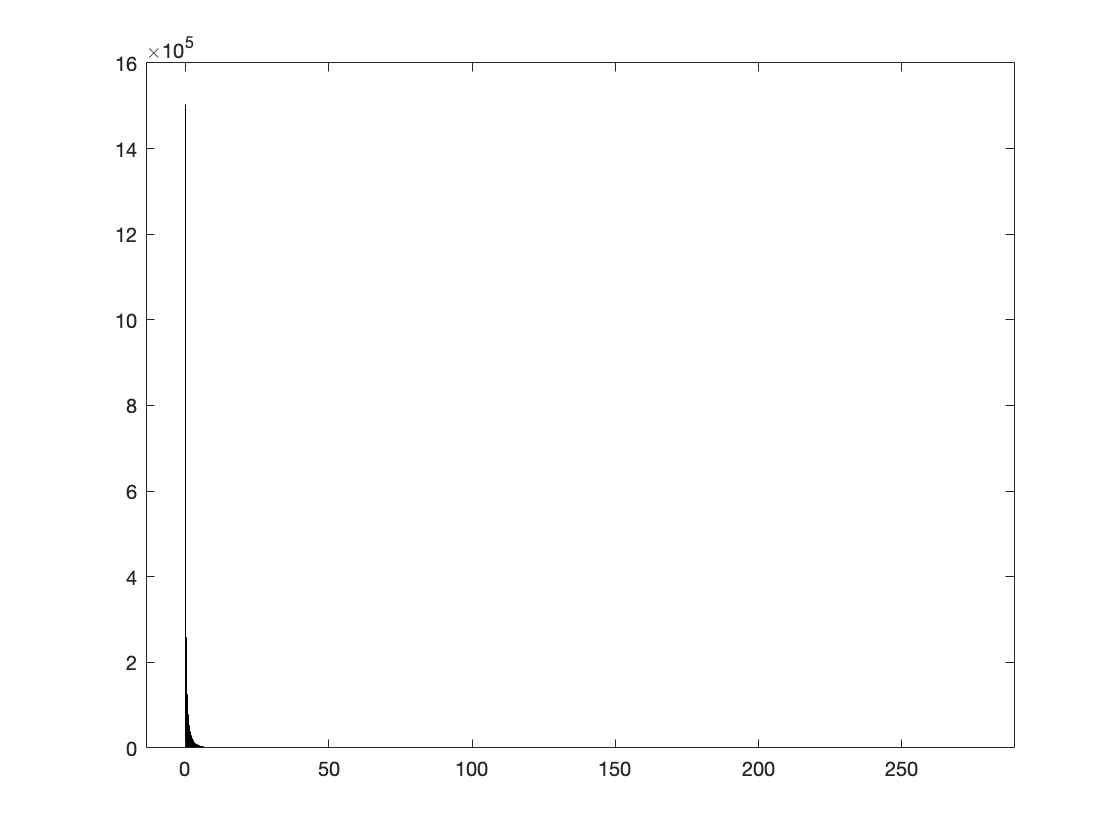


figure;    
histogram(q);

### Generate the first S raw moments of q and use SDP to obtain the required probabilistic threshold

Since the distance measure is calculated for T time steps, we can calculate the moments of it and use the moments data to design a tighter detector threshold. Remember the alarms are raised when $$q_t > \alpha$$.

% Specify the number of moments in hand
S = 4;

% Compute the First S Raw Moments
q_raw_moments = Compute_Moments_Of_Q(S, q);

The Mean of q_t is : 1.008 
The Central Moments of q are: 
   1.0e+12 *

    0.0000
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0215
    5.2706

The Raw Moments of q are: 
   1.0e+12 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0221
    5.4462

Feasible Moment Sequence !!! 



% Using the computed raw moments, compute the desired detector thrsshold.
[optThreshold, polybnd] = Solve_SDP(sys, S, q_raw_moments);


 Starting iteration number: 1
 The current threshold is: 10.000 
Size: 31  10
 
SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Put 5 free variables in a quadratic cone
eqs m = 10, order n = 13, dim = 33, blocks = 6
nnz(A) = 38 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.37E+02 0.000
  1 :   2.40E+00 8.25E+01 0.000 0.2449 0.9000 0.9000   1.00  1  1  2.3E+00
  2 :  -6.12E-01 7.72E+00 0.000 0.0936 0.9900 0.9900   1.06  1  1  1.1E+00
  3 :  -2.26E-01 2.52E+00 0.000 0.3260 0.9000 0.9000   1.95  1  1  5.8E-01
  4 :  -2.08E-01 6.74E-01 0.000 0.2678 0.9000 0.9000   2.80  1  1  3.5E-01
  5 :  -1.29E-01 1.96E-01 0.000 0.2912 0.9000 0.9000   1.13  1  1  4.3E-01
  6 :  -1.54E-02 4.47E-02 0.000 0.2278 0.9000 0.9000   1.33  2  2  2.6E-01
  7 :   2.05E-02 7.84E-03 0.000 0.1753 0.9000 0.9069   1.26  2  2  8.3E-02
  8 :   3.26E-

### Analyze the detector threshold using the q data and find the worst case false alarm rate

% Infer the resulting false alarm rates with different threshold values
fprintf('\n The best polynomial bound of the indicator function is');


 The best polynomial bound of the indicator function is

disp(polybnd);

$$4.445e-7\,z^{4}-0.0001807\,z^{3}+0.01848\,z^{2}-0.02277\,z+0.007056$$

polycoeffs = flip(coeffs(polybnd));
fprintf('\n The optimal threshold is: %.3f \n', optThreshold);


 The optimal threshold is: 8.340 


fprintf('\n The False Alarm Rate for MLQG Using 4 Moments is: %.6f \n', sum(q > optThreshold)/(T+1));


 The False Alarm Rate for MLQG Using 4 Moments is: 0.009001 


fprintf('\n The False Alarm Rate for LQG data Using 4 Moments is: %.6f \n', sum(q_lqg > optThreshold)/(T+1));


 The False Alarm Rate for LQG data Using 4 Moments is: 0.006551 


### Plot the results

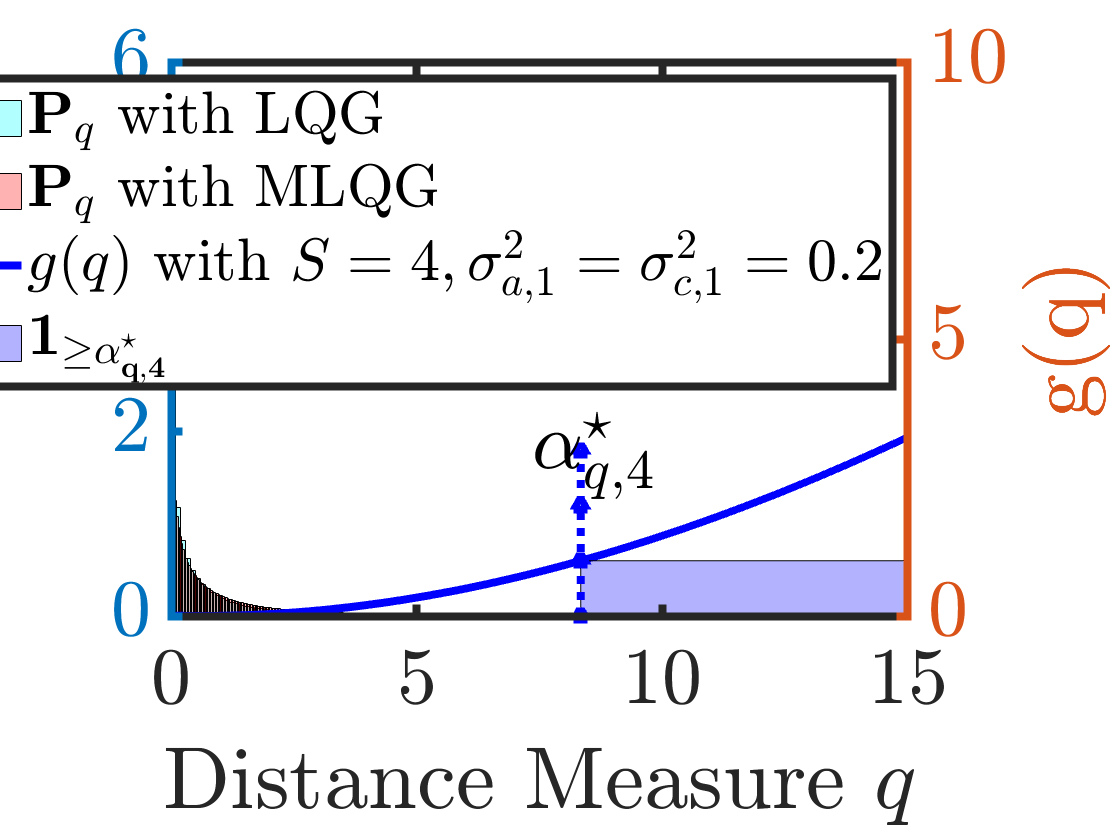

%% Plot the polynomial bounding the indicator function
t      = 0:0.001:15;
poly_q = double(vpa(polycoeffs,6));

figure;
yyaxis left
histogram(q_lqg,"Normalization","pdf", 'FaceColor', 'cyan', 'FaceAlpha', 0.3);
ylabel('$P_{q}$','Interpreter','latex', 'FontSize', 40);
hold on; 
histogram(q,"Normalization","pdf", 'FaceColor', 'red', 'FaceAlpha', 0.3);
hold on;

% Plot the moment based polynomials
yyaxis right
% Tightened Polynomial bound for S = 4
plot(t, polyval(poly_q,t),'-b', 'LineWidth',3);
hold on;
% Plot Indicator Functions for S = 4
x_indicator = [0 optThreshold optThreshold t(end) t(end)];
y_indicator = [0 0 1 1 0];
patch(x_indicator,y_indicator,'blue', 'FaceAlpha',0.3);
hold on;
% Plot the threshold
y_opt = [0 1 2 3];
len_y = length(y_opt);
% k = 4
x_a_opt = optThreshold*ones(1,len_y);
plot(x_a_opt, y_opt, ':b', 'Marker','^');
text(x_a_opt(end)-1.0, y_opt(end), '$\alpha^{\star}_{q,4}$','Interpreter','latex', 'FontSize', 40)
hold off;
xlim([0,t(end)])
ylim([0,10])
xlabel('Distance Measure $q$','Interpreter','latex', 'FontSize', 40);
ylabel('g(q)','Interpreter','latex', 'FontSize', 40);
legend('$\mathbf{P}_{q}$ with LQG', '$\mathbf{P}_{q}$ with MLQG', '$g(q)$ with $S = 4, \sigma^{2}_{a,1} = \sigma^{2}_{c,1} = 0.2$', '$\bf{1}_{\geq \alpha^{\star}_{q,4}}$', 'FontSize', 30, 'Interpreter','latex');
a = findobj(gcf, 'type', 'axes');
h = findobj(gcf, 'type', 'line');
set(h, 'linewidth', 4);
set(a, 'linewidth', 4);
set(a, 'FontSize', 40);
set(gca,'TickLabelInterpreter','latex');
hold off;

% Save the data
savefilename_1 = 'data0';
savefilename_2 = '.mat';
savefilename = strcat(strcat(savefilename_1, num2str(100*sys.delta_var_A)), savefilename_2);
save(savefilename);

### HELPER FUNCTIONS

### A) Function to Define the Inverted Pendulum System

function sys = Define_Pendulum_System(n,m,p,dt)

    % Define some symbols
    syms x1 x2 mc x1 u
    
    % Nonlinear dynamics
    % x1 is angle of pendulum from downward vertical
    % x2 is angular rate of pendulum
    x1dot = x2;
    x2dot = -mc*sin(x1) + u;
    
    % x and u input vectors for Jacobian function
    Vx = [x1;x2];
    Vu = [u];
    
    % Get the jacobian
    f = [x1dot; x2dot];
    A = jacobian(f, Vx);
    B = jacobian(f, Vu);
    C = [1 0];
    D = [0];
    
    % Evaluate the Jacobian at the vertical equilibrium (pi,0)    
    fprintf('Defining the Jacobian');
    x1 = pi; % vertical upright position
    x2 = 0;  % zero angular rate 
    
    % define the unknown parameter p
    mc = 10;  % True value of mass constant
    
    % Get the true discrete time linearized dynamics evaluated at the equilibrium point
    A_true = eval(A)*dt + eye(n);
    B_true = eval(B)*dt;
    
    % Nominal value
    mc = 5;
    
    % Get the linearized dynamics evaluated at the equilibrium point
    A = eval(A) ;
    B = eval(B);
    
    % Get the discrete time dynamics using forward Euler discretization
    A = eye(n) + dt*A;
    B = dt*B;
    
    % Define the state and control penalty matrices
    sys.Q = eye(n);
    sys.R = eye(m);
    
    % Prepare the sys object
    sys.A = A;
    sys.B = B;
    sys.C = C;
    sys.D = D;
    sys.A_true = A_true;
    sys.B_true = B_true;
    sys.sssys = ss(A,[B B],C,[zeros(1,1) zeros(1,1)]); % ss(A, B, C, D, -1);
    
    % Define Multiplicative noise details
    sys.delta_mu = 0; % Multiplicative noise mean
    sys.delta_var_A = 0.10; % A matrix Multiplicative noise variance
    sys.delta_std_A = sqrt(sys.delta_var_A); % A matrix Multiplicative noise std deviation
    sys.delta_var_B = 0.01; % B matrix Multiplicative noise variance
    sys.delta_std_B = sqrt(sys.delta_var_B); % B matrix Multiplicative noise std deviation
    sys.delta_var_C = 0.10; % C matrix Multiplicative noise variance
    sys.delta_std_C = sqrt(sys.delta_var_C); % C matrix Multiplicative noise std deviation
    
    % Infer the system dimensions
    [sys.n, sys.m] = size(B);
    [sys.p, ~] = size(C);
    sys.nm = sys.n*sys.m;
    sys.pn = sys.p*sys.n;
    
    % Define the # of direction matrices
    sys.na = 1; % # of A direction matrices
    sys.nb = 0; % # of B direction matrices
    sys.nc = 1; % # of C direction matrices
    
    % Define the uncertain direction matrices
    if(sys.na)
        % Define Place holder to store uncertain direction matrices of A
        sys.Ai = cell(1,sys.na); 
        % Define Place holder to store second moment of uncertain direction matrices of A
        sys.sigmaAprime = zeros((sys.n)^2, (sys.n)^2);
        for i = 1:sys.na
            sys.Ai{i} = [0 0; 1 0];
            sys.sigmaAprime = sys.sigmaAprime + sys.delta_var_A*kron(sys.Ai{i}, sys.Ai{i});
        end                
    else
        fprintf('\n No uncertainty in A matrix');
        sys.Ai = {};
        sys.sigmaAprime = zeros((sys.n)^2, (sys.n)^2);           
    end
    
    if(sys.nb)
        % Define Place holder to store uncertain direction matrices of B
        sys.Bi = cell(1,sys.nb); 
        % Define Place holder to store second moment of uncertain direction matrices of A
        sys.sigmaBprime = zeros((sys.n)^2, (sys.m)^2);
        for i = 1:sys.nb            
            % Define Bi matrices like this
            % sys.Bi{i} = [0 0; 1 0];
            % sys.sigmaBprime = sys.sigmaBprime + sys.delta_var_B*kron(sys.Bi{i}, sys.Bi{i});
        end     
    else
        fprintf('\n No uncertainty in B matrix');
        sys.Bi = {};
        sys.sigmaBprime = zeros((sys.n)^2, (sys.m)^2);                
    end
    
    if(sys.nc)
        % Define Place holder to store uncertain direction matrices of C
        sys.Ci = cell(1,sys.nc); 
        % Define Place holder to store second moment of uncertain direction matrices of A
        sys.sigmaCprime = zeros((sys.p)^2, (sys.n)^2);
        for i = 1:sys.nc
            % Define Ci matrices like this
            sys.Ci{i} = [0.1 0]; 
            sys.sigmaCprime = sys.sigmaCprime + sys.delta_var_C*kron(sys.Ci{i}, sys.Ci{i});
        end                         
    else
        fprintf('\n No uncertainty in C matrix');
        sys.Ci = {};
        sys.sigmaCprime = zeros((sys.p)^2, (sys.n)^2);               
    end        
    
    % Define the noise covariances
    sys.muNoiseW = zeros(n,1); % Process noise mean
    sys.muNoiseV = zeros(p,1); % sensor noise mean
    sys.sigmaW = 2*eye(n); % process noise covariance
    sys.sigmaV = 2; % sensor noise covariance
    sys.sigmaNoise = blkdiag(sys.sigmaW, sys.sigmaV); % joint noise covariance
    sys.alarmRate = 0.05; % desired false alarm rate
    sys.chi2Alpha = chi2inv(1-sys.alarmRate,p); % threshold from chi-squared detector
    sys.chebyshevAlpha = p/sys.alarmRate; % threshold from first 2 moments of r using Chebyshev bound
    
end

### B) Function to Generate the True System Data

function q = Generate_Distance_Measure_Data(sys, x_0, T)
    
    [n,m] = size(sys.B);
    [p,~] = size(sys.C);      
    
    % Generate the noises from multivariate laplacian
    w_t = mvlaprnd(n, sys.muNoiseW, sys.sigmaW, T+1);
    v_t = mvlaprnd(p, sys.muNoiseV, sys.sigmaV, T+1);
    
    % Placeholders for states and outputs
    x = zeros(n,T+1);    
    e = zeros(n,T+1);
    r = zeros(T+1,1);
    q = zeros(T+1,1);
    
    % Populate the initial conditions    
    x(:,1) = x_0;    
    
    % Simulate and generate the system data
    for t = 2:T+1          
        gamma_t = sys.delta_mu + sys.delta_std_A*randn; % = a + (b-a)*rand;                
        kappa_t = sys.delta_mu + sys.delta_std_C*randn; % = a + (b-a)*rand;                 
        A_multi = zeros(size(sys.A));
        C_multi = zeros(size(sys.C));
        for i = 1:sys.na
            A_multi = A_multi + gamma_t*sys.Ai{i};        
        end
        for i = 1:sys.nc
            C_multi = C_multi + kappa_t*sys.Ci{i};        
        end        
        A_pert = sys.A + A_multi;
        x(:,t) = (A_pert + sys.B*sys.K)*x(:,t-1) - sys.B*sys.K*e(:,t-1) + w_t(:,t-1);
        % e(:,t) = (sys.A - sys.L*sys.C)*e(:,t-1) + A_multi*x(:,t-1) - sys.L*v_t(:,t-1) + w_t(:,t-1);
        e(:,t) = (sys.A - sys.L*sys.C)*e(:,t-1) + (A_multi - sys.L*C_multi)*x(:,t-1) - sys.L*v_t(:,t-1) + w_t(:,t-1);
        r(t-1,:) = sys.C*e(:,t-1) + C_multi*x(:,t-1) + v_t(:,t-1); 
        q(t-1,1) = (r(t-1,:)*r(t-1,:))/sys.sigmaR;        
    end
    
    figure;
    histogram(r)   
    
end

### C) Value Iteration to Solve the Coupled Algebraic Riccati Equations (Coupled-ARE)

function [K,L, SigmaE] = Solve_Coupled_Riccati(sys)
    % Function Solve_Coupled_Riccati solves coupled riccati equation via value
    % iteration
    
    % Unwrap sys object
    A = sys.A;    
    B = sys.B;
    C = sys.C;    
    Q = sys.Q;
    R = sys.R;  
    na = sys.na;
    nb = sys.nb;
    nc = sys.nc;    
    Ai = sys.Ai;
    Bi = sys.Bi;
    Ci = sys.Ci;
    delta_var_A = sys.delta_var_A;
    delta_var_B = sys.delta_var_B;
    delta_var_C = sys.delta_var_C;
    SigmaW = sys.sigmaW;    
    SigmaV = sys.sigmaV;
    
    % Set options    
    eps = 1e-8; % convergence tolerance   
    max_iters = 1000; % maximum iteration limit
    Pelmax = 1e25; % maximum value of P_{i}'s , i = 1,2,3,4.
    [n,m] = size(B); % state and input dimensions   
    [p,~] = size(R); % output dimension   
    
    % Initialize values
    iter = 0; % variable to count the iterations
    P1 = zeros(n,n); % Initial Value of P1
    P2 = zeros(n,n); % Initial Value of P2
    P3 = zeros(n,n); % Initial Value of P3
    P4 = zeros(n,n); % Initial Value of P4
    K  = zeros(m,n); % Initial Value of K
    L  = zeros(n,p); % Initial Value of L
    
    % Record previous iterate
    P1_prev = P1;
    P2_prev = P2;
    P3_prev = P3;
    P4_prev = P4;
    
    % Flags for convergence    
    converged = 0;
    
    % Loop until covergence or exceed max_iters
    while true        
        
        % Certain parts                
        Q_AP1Acer = Q + A'*P1*A;
        R_BP1Bcer = R + B'*P1*B;
        W_AP3Acer = SigmaW + A*P3*A';      
        V_CP3Ccer = SigmaV + C*P3*C';        
        ALCcer = (A-L*C)'*P2*(A-L*C);
        ABKcer = (A+B*K)*P4*(A+B*K)'; 

        % Place holders for uncertain parts
        AP1Aunc = zeros(n, n);
        AP2Aunc = zeros(n, n);
        AP3Aunc = zeros(n, n);
        AP4Aunc = zeros(n, n);
        BP1Bunc = zeros(m, m);
        BP2Bunc = zeros(m, m);
        BKP4Bunc = zeros(n, n);
        CP3Cunc = zeros(p, p);
        CP4Cunc = zeros(p, p);
        CLP2Cunc = zeros(n, n);
        
        % Uncertain parts involving A components
        if(na)   
            for i = 1:na         
                AP1Aunc = AP1Aunc + delta_var_A*Ai{i}'*P1*Ai{i};            
                AP2Aunc = AP2Aunc + delta_var_A*Ai{i}'*P2*Ai{i};            
                AP3Aunc = AP3Aunc + delta_var_A*Ai{i}*P3*Ai{i}';                
                AP4Aunc = AP4Aunc + delta_var_A*Ai{i}*P4*Ai{i}';
            end
        end
        
        % Uncertain parts involving B components
        if(nb)            
            for i = 1:nb
                BP1Bunc = BP1Bunc + delta_var_B*Bi{i}'*P1*Bi{i};            
                BP2Bunc = BP2Bunc + delta_var_B*Bi{i}'*P2*Bi{i};            
                BKP4Bunc = BKP4Bunc + delta_var_B*Bi{i}*K*P4*K'*Bi{i}';
            end
        end
        
        % Uncertain parts involving C components
        if(nc)            
            for i = 1:nc                  
                CP3Cunc = CP3Cunc + delta_var_C*Ci{i}*P3*Ci{i}';                        
                CP4Cunc = CP4Cunc + delta_var_C*Ci{i}*P4*Ci{i}';            
                CLP2Cunc = CLP2Cunc + delta_var_C*Ci{i}'*L'*P2*L*Ci{i};
            end
        end
        
        % Recurse
        K_alfa = R_BP1Bcer + BP1Bunc + BP2Bunc;
        L_alfa = V_CP3Ccer + CP3Cunc + CP4Cunc;
        K = -inv(K_alfa)*B'*P1*A;
        L = A*P3*C'*inv(L_alfa); 
        P1 = Q_AP1Acer + AP1Aunc + AP2Aunc - K'*K_alfa*K + CLP2Cunc;
        P2 = ALCcer + K'*K_alfa*K;        
        P3 = W_AP3Acer + AP3Aunc + AP4Aunc - L*L_alfa*L' + BKP4Bunc;
        P4 = ABKcer + L*L_alfa*L';
        absP1 = abs(P1);     
        absP2 = abs(P2);     
        absP3 = abs(P3);     
        absP4 = abs(P4);     
        
        % Check for stopping condition
        P1_conv = norm(P1 - P1_prev, 'fro')/norm(P1, 'fro');
        P2_conv = norm(P2 - P2_prev, 'fro')/norm(P2, 'fro');
        P3_conv = norm(P3 - P3_prev, 'fro')/norm(P3, 'fro');
        P4_conv = norm(P4 - P4_prev, 'fro')/norm(P4, 'fro');
        P1_extc = any(absP1 > Pelmax, 'all');
        P2_extc = any(absP2 > Pelmax, 'all');
        P3_extc = any(absP3 > Pelmax, 'all');
        P4_extc = any(absP4 > Pelmax, 'all');
        
        if(P1_conv < eps && P2_conv < eps && P3_conv < eps && P4_conv < eps) 
            converged = 1;
            fprintf('Value Iteration Converged \n');  
            display(P1)
            display(P2)
            display(P3)
            display(P4)
            break;
        end
        if(iter >= max_iters || P1_extc || P2_extc || P3_extc || P4_extc)            
            converged = 0;
            fprintf('Value iteration has reached maximum iterations !!! \n');
            break;
        else
            iter = iter + 1;
        end
        
        % Record the previous iterate
        P1_prev = P1;
        P2_prev = P2;
        P3_prev = P3;
        P4_prev = P4;
        
    end
    
    % Compute the gains
    if(converged == 1)
        K = -inv(K_alfa)*B'*P1*A;
        L = A*P3*C'*inv(L_alfa);
        SigmaE = P3;
    else
        K = [];
        L = [];
        SigmaE = [];
    end

end

### D) Compute First S Raw Moments of distance measure q

function q_raw_moments = Compute_Moments_Of_Q(S, q)

    % Compute the first S moments of q_t 
    % Compute central moments & then infer raw moments from it
    q_central_moments = [];      % list to store the central moments
    q_mean            = mean(q); % Mean of the q_t data
    
    % Calculate the central moments upto order 2S+1
    for j = 1:2*S+1
        jj = j - 1;
        q_central_moments = [q_central_moments moment(q, jj)];
    end
    fprintf('The Mean of q_t is : %.3f \n', q_mean);
    disp('The Central Moments of q are: ');
    disp(q_central_moments');
    q_raw_moments = CentralToRawMoments(q_central_moments, q_mean);
    disp('The Raw Moments of q are: ');
    disp(q_raw_moments);
    
    % Check if Raw Moments are feasible 
    infeasible_flag = CheckMomentsFeasibility(q_raw_moments, S);
    
    % Display Error if feasible moments are obtained
    if infeasible_flag == 0
        disp('Feasible Moment Sequence !!! ');    
    elseif infeasible_flag == 1
        disp('Infeasible Moment Sequence !!! ');    
    end
end

### E) Solve SDP to get a threshold$\alpha$corresponding to a desired false alarm rate $\mathcal{A}$.

function [optThreshold, polybnd] = Solve_SDP(sys, S, q_raw_moments)
    momentsData   = q_raw_moments(1:S+1);
    num_moments   = S;
    thresholdTol  = 1e-04;           
    thresholdHigh = sys.chebyshevAlpha;  % Set chebyshevAlpha as upper threshold
    thresholdLow  = 0;   
    loopCounter   = 0; 
    
    % Do bisection search
    while(abs(thresholdHigh - thresholdLow) > thresholdTol)
        
        % Increment the Loop Counter and display it
        loopCounter = loopCounter + 1;
        fprintf('\n Starting iteration number: %d', loopCounter);
        
        % Set the threshold and get the probabilty bound    
        optThreshold  = mean([thresholdHigh thresholdLow]); 
        fprintf('\n The current threshold is: %.3f \n', optThreshold);
        
        % Create the Symbolic variables
        z             = sym('z');
        moments_coeff = sym('y_%d',[1 num_moments+1]);
        
        % Define the Support of the q_t random variable
        R = [0,inf];
        
        % Defining event whose probability we want to bound P(X > threshold)
        E = [optThreshold, max(R)];
        
        % =============================================
        % Define the SOS Program
        % =============================================
        
        % Constructing and solving the SOS program
        prog = sosprogram([z], moments_coeff);  
        
        % Create a vector for moment sequence index
        mom_sequence = 0:num_moments;
        
        % Create a vector of monomials in q upto order given by mom_sequence
        monomial_vec = monomials([z],mom_sequence);    
        
        % Create a polynomial using the moments_coeff and monomial_vec 
        rand_var_poly = moments_coeff*monomial_vec;
        
        if(loopCounter == 0)
            disp('The monomial basis is');
            disp(monomial_vec);
            disp('The objective function is')
            disp(rand_var_poly);        
        end
        
        % Polynomial should be Nonnegative on the support
        prog = sosineq(prog, rand_var_poly, R);
        
        % Polynomial should be Greater than one on the event
        prog = sosineq(prog, rand_var_poly-1, E);
        
        % Define the objective function to minimize    
        obj_bnd = vpa(moments_coeff*momentsData,4);
        
        % =============================================
        % Solve the SOS Program
        % =============================================
        
        % Objective: minimize the bound
        prog = sossetobj(prog,obj_bnd);
        
        % Solve using SOSTOOLS
        prog = sossolve(prog);
        
        % Get the solution from the SOS solver
        BND     = sosgetsol(prog,obj_bnd,16);
        polybnd = sosgetsol(prog,rand_var_poly);
        
        % Display the current probability bound
        fprintf('\n The current probability bound is: %.4f', BND);
        
        % Depending upon the desired alarmRate do a bisection search
        if(BND < sys.alarmRate)
            thresholdHigh = optThreshold;
        else
            thresholdLow = optThreshold;
        end
    end
    fprintf('\n The optimal threshold is: %.3f', optThreshold);    
end

### F) Find steady state moments of estimation error, states and residual

function steady_moments = Compute_Steady_State_Moments(sys)
% Function Compute_Steady_State_Moments returns the steady state moments
% of states, estimation error and the residual
    
    % Get required matrices
    A = sys.A;
    B = sys.B;
    C = sys.C;
    L = sys.L;
    K = sys.K;    
    BK = sys.B*sys.K;
    LC = sys.L*sys.C;    
    sigmaW = sys.sigmaW;
    sigmaV = sys.sigmaV;
    sigma_A_prime = sys.sigmaAprime;
    sigma_B_prime = sys.sigmaBprime;
    sigma_C_prime = sys.sigmaCprime;
    
    % Get dimensions
    [n,m] = size(B);
    [p,n] = size(C);
    
    % Populate H matrix entry-by-entry. H is a 4x4 matrix
    H_11 = sigma_A_prime + kron(A, A);
    H_12 = kron(BK, A);
    H_13 = kron(A, BK);
    H_14 = (kron(B, B) + sigma_B_prime)*kron(K, K);
    H_21 = kron(LC, A);
    H_22 = kron(A+BK-LC, A);
    H_23 = kron(LC, BK);
    H_24 = kron(A+BK-LC, BK);
    H_31 = kron(A, LC);
    H_32 = kron(BK, LC);
    H_33 = kron(A, A+BK-LC);
    H_34 = kron(BK, A+BK-LC);
    H_41 = kron(L,L)*(kron(C,C) + sigma_C_prime);
    H_42 = kron(A+BK-LC, LC);
    H_43 = kron(LC, A+BK-LC);
    H_44 = kron(A+BK-LC, A+BK-LC);
    
    % Form the H matrix
    Hcell = {H_11, H_12, H_13, H_14; H_21, H_22, H_23, H_24; H_31, H_32, H_33, H_34; H_41, H_42, H_43, H_44};
    H = cell2mat(Hcell);
    
    % Form phi, V matrices
    V = [sigmaW(:); sigmaV(:)];
    Phi = [kron(eye(n), eye(n)) zeros(n*n,1);
           zeros(n*n,n*n)       zeros(n*n,1);
           zeros(n*n,n*n)       zeros(n*n,1);
           zeros(n*n,n*n)       kron(L,L)];    
    
    % Obtain state state moments
    mathcal_X_infty = inv(eye(4*n*n) - H)*Phi*V;
    
    % Retrieve steady state components
    X_infty = mathcal_X_infty(1:n*n);
    X_infty_tilde = mathcal_X_infty(n*n+1:2*n*n);
    X_infty_breve = mathcal_X_infty(2*n*n+1:3*n*n);
    X_infty_hat = mathcal_X_infty(3*n*n+1:end);    
    
    % Obtain steady state estimation error covariance
    E_infty = X_infty - X_infty_tilde - X_infty_breve + X_infty_hat;
    R_infty = kron(C,C)*E_infty + sigmaV(:);    
    
    % Reshape the matrices
    steady_moments.X_infty = reshape(X_infty, [n,n]);
    steady_moments.E_infty = reshape(E_infty, [n,n]);
    steady_moments.R_infty = reshape(R_infty, [p,p]);    
    
end